# Redes Neuronales

# Aprendizaje no Supervisado

# Tarea 9

# Dataset S3

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-08-29

tic
clc;
clear;
close all;
rng(0);
warning("off","all");

% Carga y limpieza de datos
datos = importdata("s3.txt");
X = datos(:,1:2);

% ---------------------------------------
% k-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-means")

k-means

fprintf("---------------------------------------")

---------------------------------------


n = 25

n = 25

k = 12

k = 12

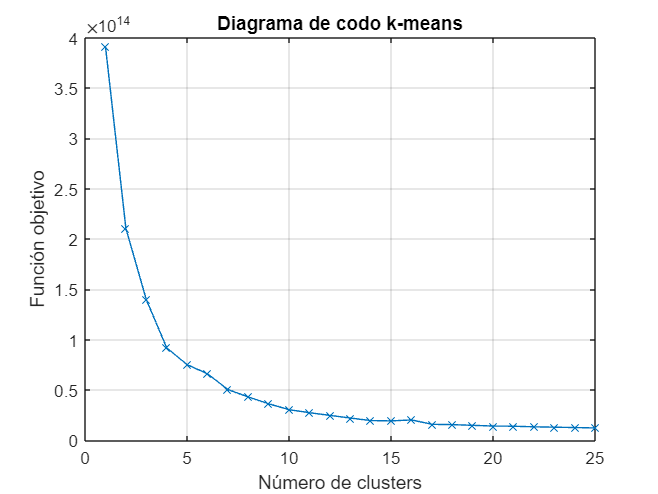

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    Jkm(i) = sum(SumD);
    Kkm(i) = i;
end

figure;
plot(Kkm, Jkm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

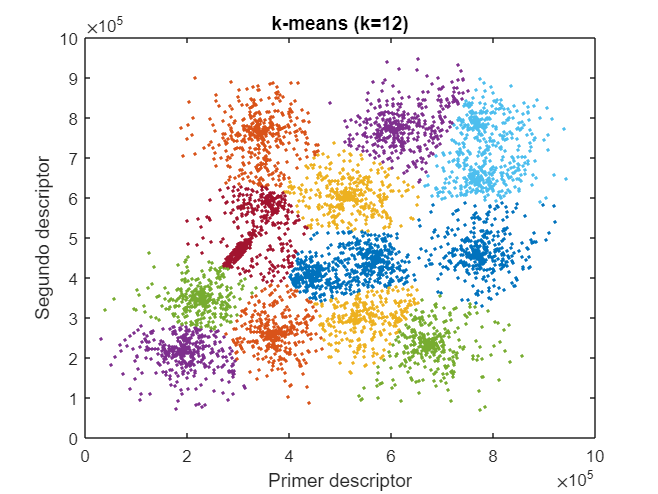


% Clustering
idx = kmeans(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-means (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-means")

Valores de métricas k-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 6.1708e+04

SSB = 2.4934e+05

WB = 2.9698

SIL = 0.6189



% ---------------------------------------
% k-medoids
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-medoids")

k-medoids

fprintf("---------------------------------------")

---------------------------------------


n = 25

n = 25

k = 12

k = 12

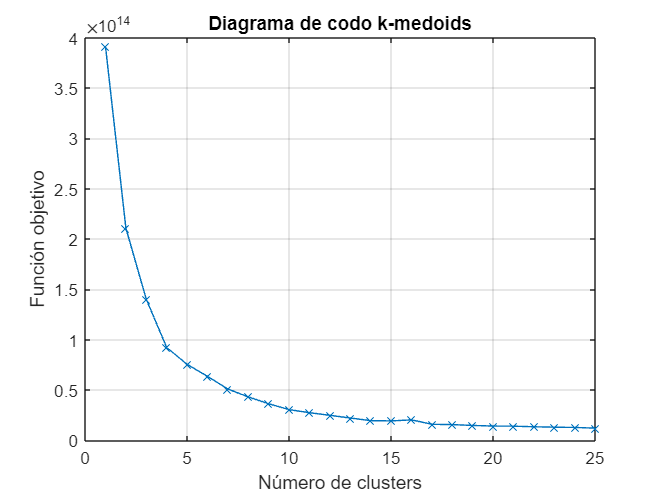

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    Jkmd(i) = sum(SumD);
    Kkmd(i) = i;
end

figure;
plot(Kkmd, Jkmd,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

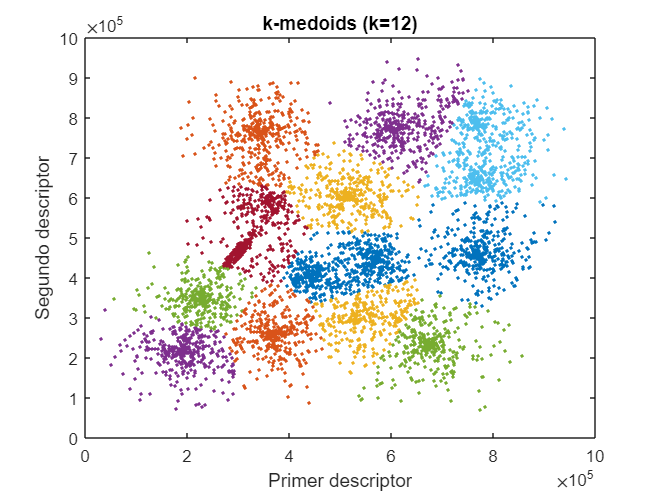


% Clustering
idx = kmedoids(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-medoids (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-medoids")

Valores de métricas k-medoids

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 6.1714e+04

SSB = 2.4925e+05

WB = 2.9712

SIL = 0.6179


% ---------------------------------------
% DBSCAN
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("DBSCAN")

DBSCAN

fprintf("---------------------------------------")

---------------------------------------

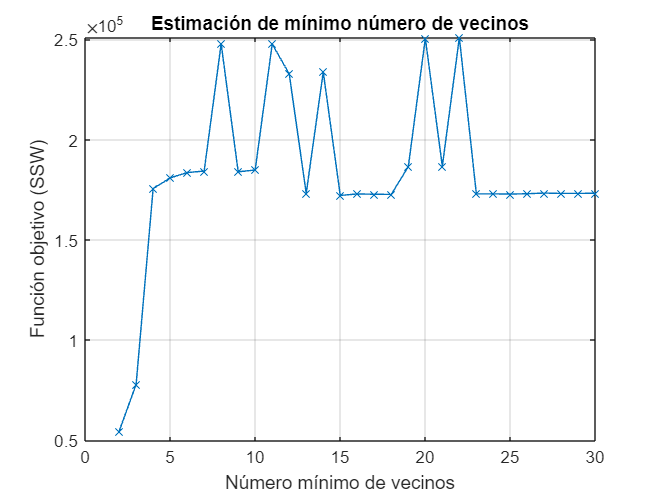


min_n = 19;
gmin_n = 2:1:30;

% Estimación número mínimo de vecinos
for i = 1:length(gmin_n)
    rng(0);
    min_ng = gmin_n(i);
    ep = clusterDBSCAN.estimateEpsilon(X,min_ng,min_ng);
    idx = dbscan(X,ep,min_ng);
    [SSWdb(i) SSBdb(i) WBdb(i) SILdb(i)] = MetricasNoSupervisado(X(idx>0,:),idx(idx>0));
    Kdb(i)=min_ng;
end

figure;
plot(Kdb,SSWdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (SSW)");
title("Estimación de mínimo número de vecinos");

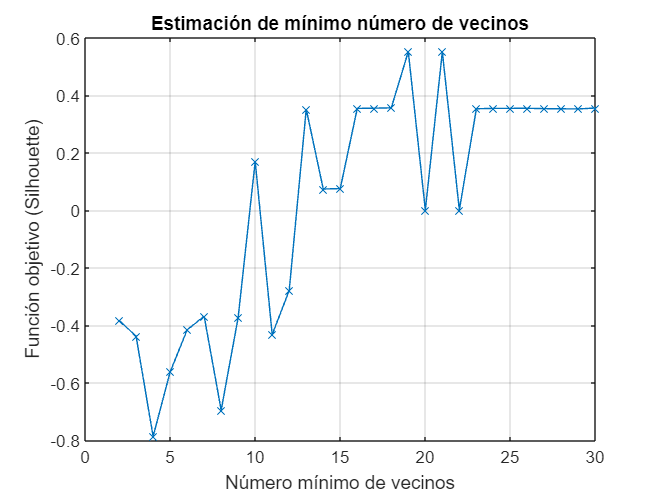


figure;
plot(Kdb,SILdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (Silhouette)");
title("Estimación de mínimo número de vecinos");



% Gráfica k-NN (Nearest Neigbor)
min_n

min_n = 19

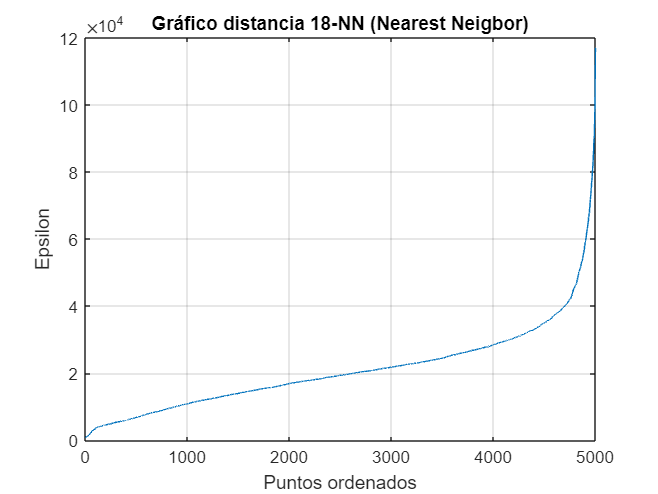

figure;
kD = pdist2(X,X,'euc','Smallest',min_n-1);
plot(sort(kD(end,:)));
title(strcat("Gráfico distancia ",string(min_n-1),"-NN (Nearest Neigbor)"));
xlabel("Puntos ordenados");
ylabel("Epsilon");
grid;


% Clustering
rng(0);
ep = clusterDBSCAN.estimateEpsilon(X,min_n,min_n)

ep = 3.0029e+04

idx = dbscan(X,ep,min_n);
clusters = unique(idx(idx>0));
num_clusters = length(clusters)

num_clusters = 2

anomalias = length(idx(idx<=0));

if (anomalias>0)
    fprintf(strcat("Existen ",string(anomalias)," anomalías"));
else
    fprintf("No existen anomalías");
end

Existen 347 anomalías

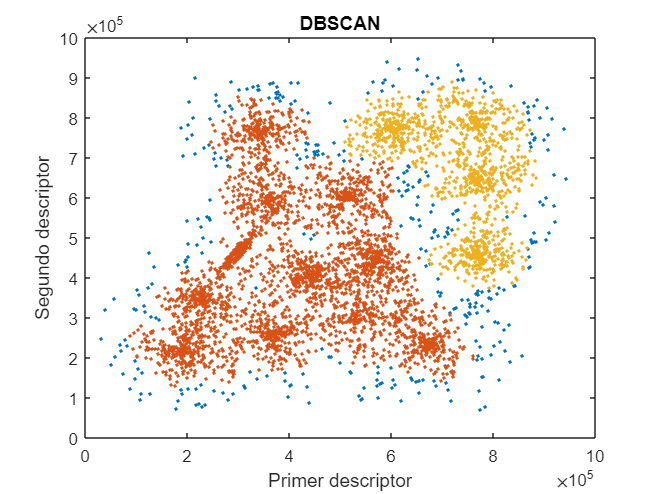


% Visualización de datos
figure;
for i=min(idx):max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("DBSCAN"));


% Métricas
fprintf("Valores de métricas DBSCAN")

Valores de métricas DBSCAN

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(idx>0,:),idx(idx>0))

SSW = 1.8648e+05

SSB = 1.5493e+05

WB = 2.4072

SIL = 0.5512


% ---------------------------------------
% Clustering Jerárquico
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Clustering Jerárquico")

Clustering Jerárquico

fprintf("---------------------------------------")

---------------------------------------


n = 25

n = 25

k = 8

k = 8

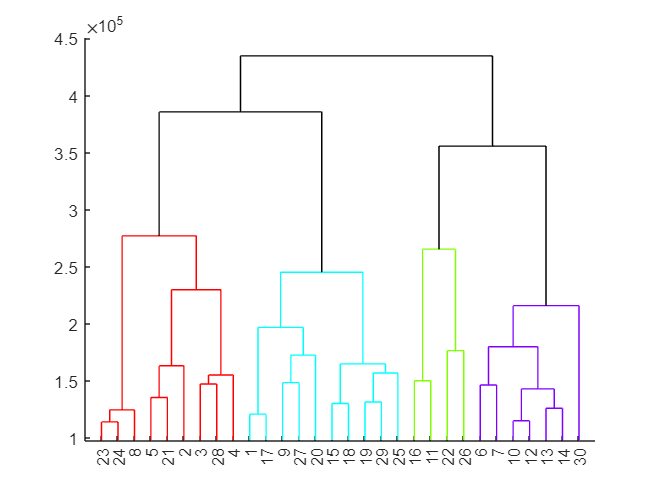

rng(0);

% Dendrograma
tree = linkage(X,"average","euclidean");
figure;
dendrogram(tree,"ColorThreshold","default")

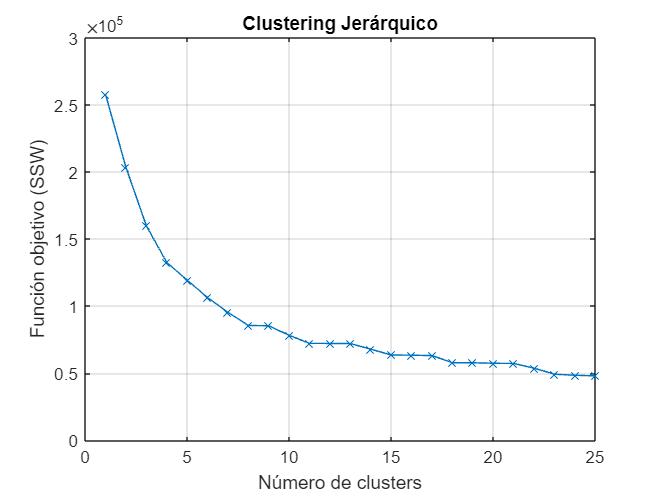


% Diagrama de codo
for i =1:n
    idx = cluster(tree,"maxclust",i);
    [SSWhc(i) SSBhc(i) WBhc(i) SILhc(i)] = MetricasNoSupervisado(X,idx);
    Khc(i)=i;
end

figure;
plot(Khc,SSWhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Clustering Jerárquico");

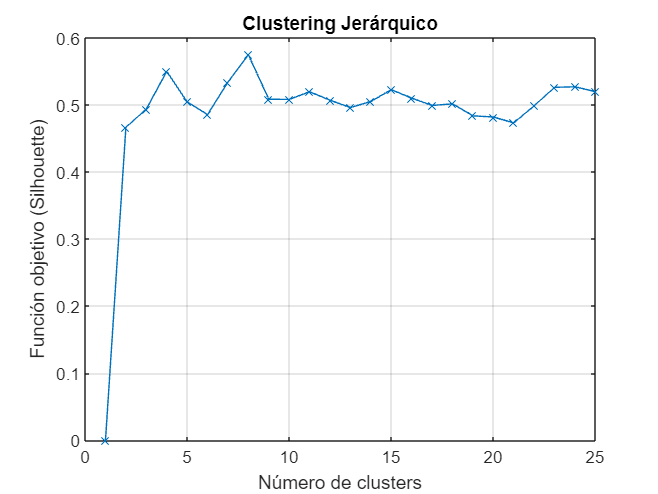


figure;
plot(Khc,SILhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (Silhouette)");
title("Clustering Jerárquico");

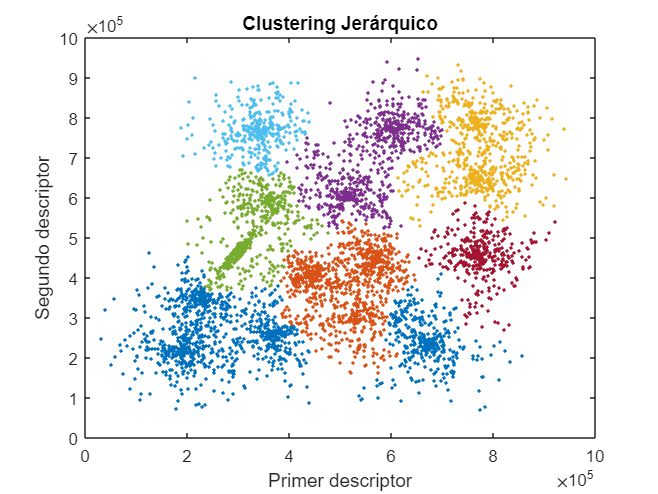


% Clusterización
idx = cluster(tree,"maxclust",k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title("Clustering Jerárquico");


% Métricas
fprintf("Valores de métricas Clustering Jerárquico")

Valores de métricas Clustering Jerárquico

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 8.5517e+04

SSB = 2.4655e+05

WB = 2.7748

SIL = 0.5743


% ---------------------------------------
% Fuzzy c-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Fuzzy c-means")

Fuzzy c-means

fprintf("---------------------------------------")

---------------------------------------


n=25

n = 25

c=12

c = 12

rng(0);

% Diagrama de codo
for i =1:n
    [centers,U] = fcm(X,i);
    Ut=U';
    idx= ones(length(Ut),1);
    maxU = max(U)';

    for j = 1:i
        s = Ut(:,j);
        f = find(s==maxU);
        idx(f)=j;
    end

    [SSWfcm(i) SSBfcm(i) WBfcm(i) SILfcm(i)] = MetricasNoSupervisado(X,idx);
    Kfcm(i)=i;
end

Iteration count = 1, obj. fcn = 20610582.657135
Iteration count = 2, obj. fcn = 1607761.266134
Iteration count = 3, obj. fcn = 358236.760915
Iteration count = 4, obj. fcn = 4.260110
Iteration count = 5, obj. fcn = 0.000000
Iteration count = 6, obj. fcn = 0.000000
Minimum improvement reached.
Iteration count = 1, obj. fcn = 239452049596856.781250
Iteration count = 2, obj. fcn = 195543294869959.562500
Iteration count = 3, obj. fcn = 195509631736319.531250
Iteration count = 4, obj. fcn = 195397662974992.406250
Iteration count = 5, obj. fcn = 194996381343897.375000
Iteration count = 6, obj. fcn = 193507252860915.000000
Iteration count = 7, obj. fcn = 188532794942357.625000
Iteration count = 8, obj. fcn = 177199825985477.187500
Iteration count = 9, obj. fcn = 164319250204528.500000
Iteration count = 10, obj. fcn = 157644490983295.531250
Iteration count = 11, obj. fcn = 155450160826840.812500
Iteration count = 12, obj. fcn = 154715572649727.125000
Iteration count = 13, obj. fcn = 15443646165

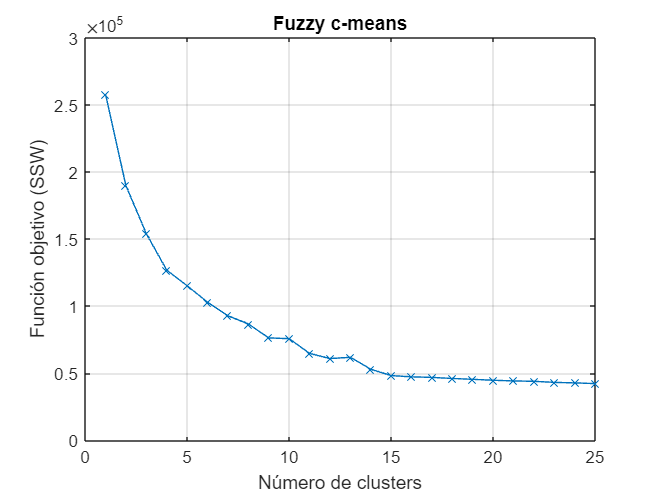


figure;
plot(Kfcm,SSWfcm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Fuzzy c-means");


% Clusterización
[centers,U] = fcm(X,c);

Iteration count = 1, obj. fcn = 43346031413607.484375
Iteration count = 2, obj. fcn = 32586458299160.601562
Iteration count = 3, obj. fcn = 32560954602980.031250
Iteration count = 4, obj. fcn = 32435006097125.613281
Iteration count = 5, obj. fcn = 31883186549884.351562
Iteration count = 6, obj. fcn = 30349167058958.007812
Iteration count = 7, obj. fcn = 27620937492306.539062
Iteration count = 8, obj. fcn = 23775005306518.656250
Iteration count = 9, obj. fcn = 20304546165840.687500
Iteration count = 10, obj. fcn = 17763156691557.539062
Iteration count = 11, obj. fcn = 16165986610570.869141
Iteration count = 12, obj. fcn = 15208071064299.666016
Iteration count = 13, obj. fcn = 14338393458498.621094
Iteration count = 14, obj. fcn = 13620694846463.419922
Iteration count = 15, obj. fcn = 13111070104101.925781
Iteration count = 16, obj. fcn = 12678724251685.761719
Iteration count = 17, obj. fcn = 12313084517010.716797
Iteration count = 18, obj. fcn = 12071363921598.117188
Iteration count = 1

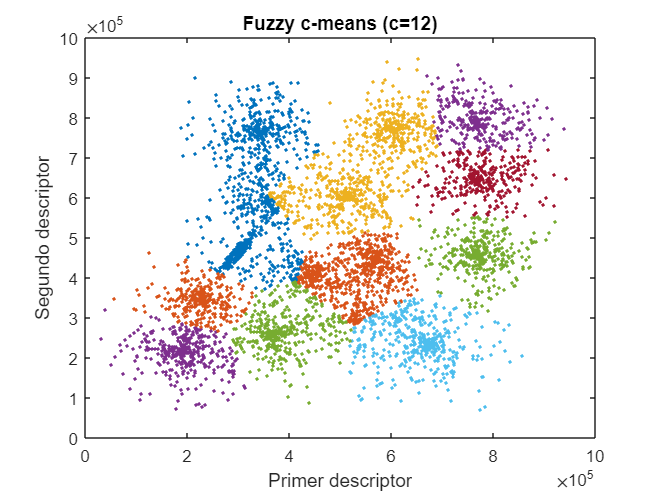

Ut=U';
idx= ones(length(Ut),1);
maxU = max(U)';

for i = 1:c
    s = Ut(:,i);
    f = find(s==maxU);
    idx(f)=i;
end

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("Fuzzy c-means (c=",string(c),")"));


% Métricas
fprintf("Valores de métricas Fuzzy c-means")

Valores de métricas Fuzzy c-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 6.0830e+04

SSB = 2.4980e+05

WB = 2.9222

SIL = 0.6266


toc

Elapsed time is 33.042630 seconds.
